# **JacobiZeta**

[Jacobi Zeta function](https://dlmf.nist.gov/22.16#iii)

## Definition


$$\mathit{\mathbf{Z}}\left(x\left|m\right.\right)\equiv \epsilon \left(x\left|m\right.\right)-\frac{E\left(m\right)}{K\left(m\right)}x$$



$$\mathit{\mathbf{Z}}\left(x,k\right)\equiv \mathit{\mathbf{Z}}\left(x\left|k^2 \right.\right)$$


where *k *is the modulus, *m *is the parameter, $\epsilon \left(x\left|m\right.\right)$ is Jacobi's second form of the elliptic integral of the second kind (Jacobi's epsilon function), $K\left(m\right)$ and $E\left(m\right)$ are complete elliptic integral of the first and the second kind. $Z\left(x\left|m\right.\right)$ is periodic part of $\epsilon \left(x\left|m\right.\right)$.  

Domain: If $-\infty <m\le 1$,(or $|k|\le 1$)  then $-\infty \le x\le \infty$. For the specified domain, the  codomain is real numbers.

Basic features:

$\mathit{\mathbf{Z}}\left(-x\left|m\right.\right)=-\mathit{\mathbf{Z}}\left(x\left|m\right.\right)$   (odd) 

 $\mathit{\mathbf{Z}}\left(x+2\textrm{nK}\left|m\right.\right)=\mathit{\mathbf{Z}}\left(x\left|m\right.\right),\;\;\;\left|x\right|<K\left(m\right)$  (periodic)

Special values:

$\mathit{\mathbf{Z}}\left(0\left|m\right.\right)=0$,   $\mathit{\mathbf{Z}}\left(K\left(m\right)\left|m\right.\right)=0$

$\mathit{\mathbf{Z}}\left(x\left|0\right.\right)=0$,  $\mathit{\mathbf{Z}}\left(x\left|1\right.\right)=\textrm{tanh}\left(x\right)$

Identities:


$$\mathit{\mathbf{Z}}\left(x+K\left(m\right)\left|m\right.\right)=\mathit{\mathbf{Z}}\left(x\left|m\right.\right)-m\;\textrm{sn}\left(x\left|m\right.\right)\textrm{cd}\left(x\left|m\right.\right)$$



$$\mathit{\mathbf{Z}}\left(x\left|m\right.\right)=Z\left(\textrm{am}\left(x\left|m\right.\right)\left|m\right.\right)$$


where* sn* and *cd* are the Jacobi elliptic functions, *am *is the Jacobi amplitude function, and $Z\left(\phi \left|m\right.\right)$ is the second form of the Jacobi zeta function.

## Syntax

Y = JacobiZeta(X,K)

y = jzeta(x,k)

Y = mJacobiZeta(X,M)

y = mjzeta(x,m)

## Description

**Y = JacobiZeta(X,K)** returns the Jacobi zeta function $\mathit{\mathbf{Z}}\left(x,k\right)$ for each element of the arrays X and K (modulus). X and K must be real and the same size or any of them can be scalar. **JacobiZeta** is the wrapper function which calls the functions **jzeta** element-wise via the function **ufun2**.

**y = elzeta(x,k)** returns the Jacobi zeta function $\mathit{\mathbf{Z}}\left(x,k\right)$ for argument x and the modulus k. It is assumed that  the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed. **jzeta** is the wrapper function which calls the functions **mjzeta**.

**Y = mJacobiZeta(X,M)** returns the Jacobi zeta function $\mathit{\mathbf{Z}}\left(x\left|m\right.\right)$ for each element of the arrays X and M (parameter). X and M must be real and the same size or any of them can be scalar. **mJacobiZeta** is the wrapper function which calls the function **mjzeta** element-wise via the function **ufun2**.

**y = mjzeta(x,m) **returns the Jacobi elliptic function $\mathit{\mathbf{Z}}\left(x\left|m\right.\right)$ for  argument x and the parameter m. It is assumed that  arguments are real scalars without check. y is NaN if any of  the arguments is invalid or convergence failed.   **mjzeta** calculte $\mathit{\mathbf{Z}}\left(x\left|m\right.\right)$ using Bulirisch's alghorithm  ([1])

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5; % |k|<= 1
x = 0.5;
[jzeta(x,k), JacobiZeta(x,k), mjzeta(x,k^2), mJacobiZeta(x,k^2)]

ans =    0.054947844253351   0.054947844253351   0.054947844253351   0.054947844253351


Accuracy. 

fprintf('%.16g\n',mjzeta(0.5,-4)) 

-0.6162027172771575


% Maple 18D -0.616202717277157 386

Special values

m = -20; % m <= 1
x = -0.5;  
mjzeta(0,m)

ans = 0

mjzeta(melK(m),m)   % m < 1 !!!

ans = 8.7904e-16

mjzeta(x,0)   

ans = 0

disp(mjzeta(x,1) - tanh(x))

     0



mjzeta(x,inf)

ans = NaN

mjzeta(-x,-inf)

ans = NaN

Identities

m = -2; 
x = 0.5; % |x| <= 1
disp(mJacobiZeta(-x,m) + mJacobiZeta(x,m)) % odd function

     0



mJacobiZeta(x,m) - mJacobiEpsilon(x,m) + mEllipticE(m)*x/mEllipticK(m)  % definition

ans = -1.1102e-16

m = -2; % |m| < 1
disp(mjzeta(x+200*melK(m),m) - mjzeta(x,m))  % periodic function

    -1.254552017826427e-14



k = 0.5;
jzeta(x+elK(k),k)-jzeta(x,k)+k^2*jsn(x,k)*jcd(x,k)  % 22.16.33 from NIST Handbook

ans = -4.1633e-17

disp(jzeta(x,k)-pjzeta(jam(x,k),k))  % check vs second form

    -1.387778780781446e-17



**Vector input**

m = [-2, -1,0]'; % |m| < 1
x = [-10, -1, 10]';
disp(mJacobiZeta(x+200*mEllipticK(m),m) - mJacobiZeta(x,m))  % periodic function

   1.0e-13 *

                   0
   0.144606548957427
                   0



**Matrix input**

Test identity

format short
m = -2; % |m|< 1
X=[-1 0 1 2; 2 3 4 8]

X =     -1     0     1     2
     2     3     4     8


disp(mJacobiZeta(X+12*mEllipticK(m),m) - mJacobiZeta(X,m))  % 22.16.29 from NIST Handbook

   1.0e-14 *

    0.1360   -0.1817    0.2720   -0.2165
   -0.2165    0.0111    0.0278    0.1860



## **Graphs **

**Example 1**

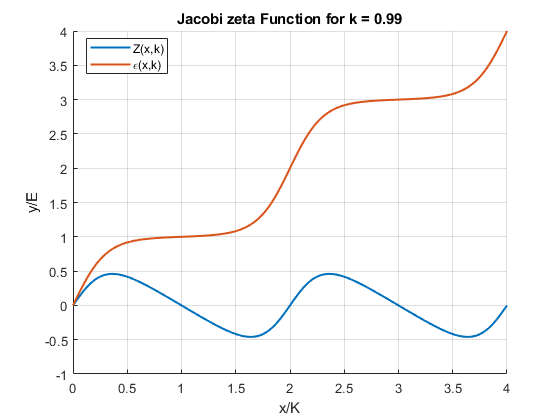

figure
hold on
x=0:0.01:4;
k = 0.99;
s = elK(k);
E = elE(k);
plot(x,JacobiZeta(s*x,k)/E,'LineWidth',1.5)
plot(x,JacobiEpsilon(s*x,k)/E,'LineWidth',1.5)
xlabel('x/K')
ylabel('y/E')
legend('Z(x,k)','\epsilon(x,k)','Location','best')
ylim([-1,4])
title(sprintf('Jacobi zeta Function for k = %g',k))
grid on

**Example 2**

Example from NIST Mathematical Functions Handbook (Fig 22.16.3)

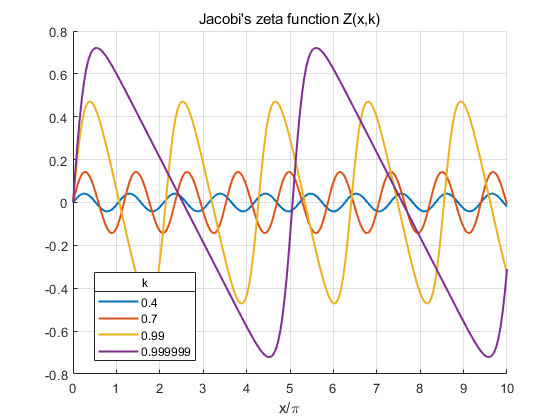

npts = 200;
k = [0.4, 0.7, 0.99, 0.999999];
s = pi;
xlim =  10;
x = linspace( 0, xlim, npts);
xx = x*s;
figure
clf
hold on
nn = length(k);
txt{nn}=[];
for n = 1:nn
    txt{n} = num2str(k(n),6);
    plot(x,JacobiZeta(xx,k(n)),'LineWidth',1.5)
end
hlg = legend(txt,'Location','best');
title(hlg, 'k','FontWeight','normal')
xlabel('x/\pi')
ylim([-0.8, 0.8]);
title('Jacobi''s zeta function Z(x,k)','FontWeight','normal')
grid on
hold off

**Example 3**

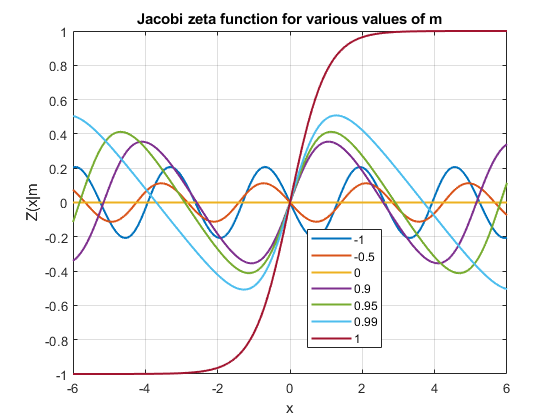

figure
X = -6:0.1:6;
M = [-1,-0.5,0,0.9,0.95,0.99,1];
EPS = zeros(length(M),length(X));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    EPS(i,:) = mJacobiZeta(X,M(i));
end
plot(X,EPS,'LineWidth',1.5)
%axis([min(X) max(X) -1.2 1.2])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Jacobi zeta function for various values of m')
xlabel('x')
ylabel('\epsilon(x|m)')
ylabel('Z(x|m');

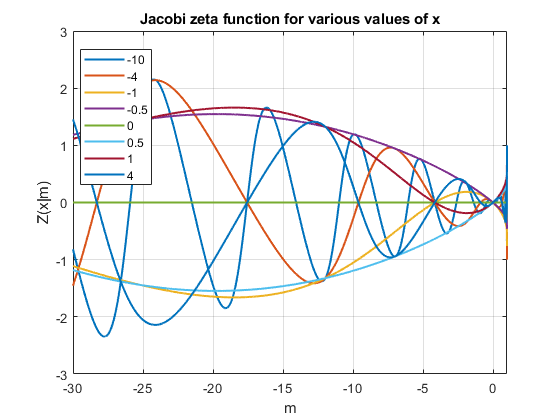

figure
M = -30:0.01:1;
X = [-10,-4,-1,-0.5,0,0.5,1,4];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mJacobiZeta(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -3 3])
grid on
legend(clg{1:length(X)},'Location','Best')
title('Jacobi zeta function for various values of x')
xlabel('m')
ylabel('Z(x|m)')

**Example 4**

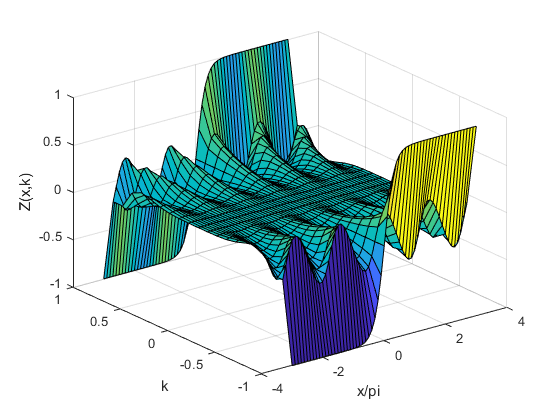

figure
x=-3:0.1:3;
k=-1:0.1:1;
[X,K]=meshgrid(x,k);
surface(X,K,JacobiZeta(pi*X,K))
view(3)
xlabel('x/pi')
ylabel('k')
zlabel('Z(x,k)')
grid on

**Example 5**

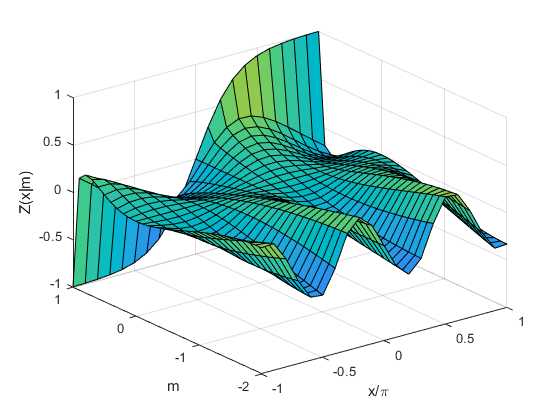

figure
x=-1:0.1:1;
m=-2:0.1:1;
[X,M]=meshgrid(x,m);
surface(X,M,mJacobiZeta(pi*X,M))
view(3)
xlabel('x/\pi')
ylabel('m')
zlabel('Z(x|m)')
grid on

**Example 6**

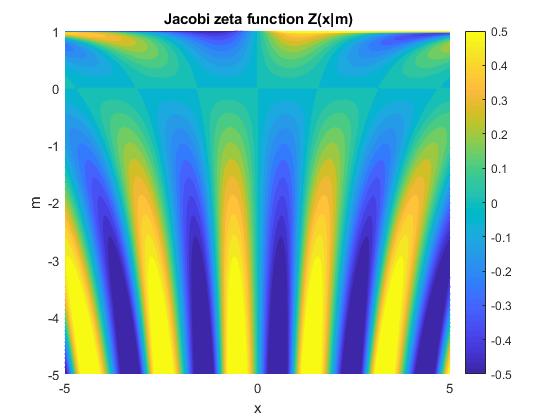

figure
f = @(x,m)mJacobiZeta(x,m);
fcontour(f,[-5,5,-5,1],'Fill','on','LevelList',-0.5:0.05:0.5,'MeshDensity',200)
title('Jacobi zeta function Z(x|m)')
colorbar
xlabel('x')
ylabel('m')
grid on

**Example 7**

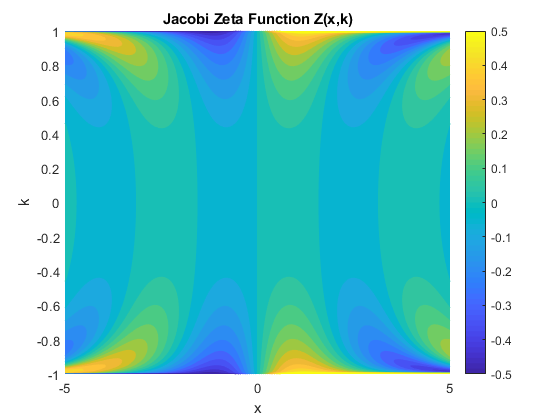

figure
f = @(x,k)JacobiZeta(x,k);
fcontour(f,[-5,5,-1,1],'Fill','on','LevelList',-0.5:0.05:0.5,'MeshDensity',200)
title('Jacobi Zeta Function Z(x,k)')
colorbar
xlabel('x')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Jacobian Elliptic Functions, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/22)

[Jacobi elliptic functions, Wikipedia](https://en.wikipedia.org/wiki/Jacobi_elliptic_functions)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions, part III. Numerische Mathematik 13, 305-315, 1969

## See Also